clear; close all; clc;

**方向角（Az，El）**

**视点（x，y，z）**

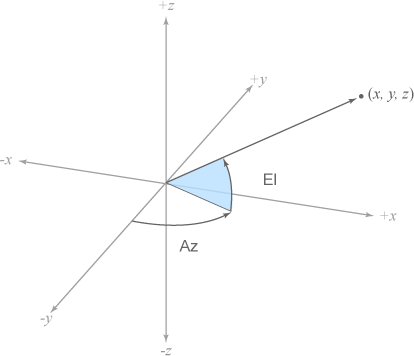

threshold = 0.58721;
loc = loc_nonoise;
frame = 68;

if ~isempty(loc1) && ~isempty(loc2)
    l1 = floor(256*threshold);
    l2 = floor(256*(1-threshold));
    bar1 = [linspace(0, 0, l1)', linspace(0, 0, l1)', linspace(1, 1, l1)'];
    bar2 = [linspace(1, 1, l2)', linspace(0, 0, l2)', linspace(0, 0, l2)'];
    colormap(cat(1, bar1, bar2))
else
    colormap([1, 0, 0])
end

loc_idxr = find(dcr >= threshold);
loc_idxb = find(dcr < threshold);

scatter3(loc(loc_idxr, 1), loc(loc_idxr, 2), loc(loc_idxr, 3), 16, 'red', 'filled');
hold on;
scatter3(loc(loc_idxb, 1), loc(loc_idxb, 2), loc(loc_idxb, 3), 16, 'blue', 'filled');
hold off;

fig = gcf;
ax = gca;

view([0, 1, 0])
xlabel('xlabel')
ylabel('ylabel')
zlabel('zlabel')
title('MinfluxDcr');
set(ax, 'xgrid', 'on');
set(ax, 'ygrid', 'on');
set(ax, 'zgrid', 'on');
set(ax, 'xminorgrid', 'on');
set(ax, 'yminorgrid', 'on');
set(ax, 'zminorgrid', 'on');
set(ax, 'FontSize', 16, 'FontWeight', 'bold', 'FontName', 'Times New Roman');

el = 0
for i = 1 : frame
    
    axis equal
    colorbar('Ticks',[0, threshold, 1]);
    scrsz = get(0, 'ScreenSize');
    set(fig, 'Position', scrsz);
    
    view(0, el)
    el = el + 360/frame;
    drawnow
    f = getframe(fig);
    im{i} = frame2im(f);
    
end

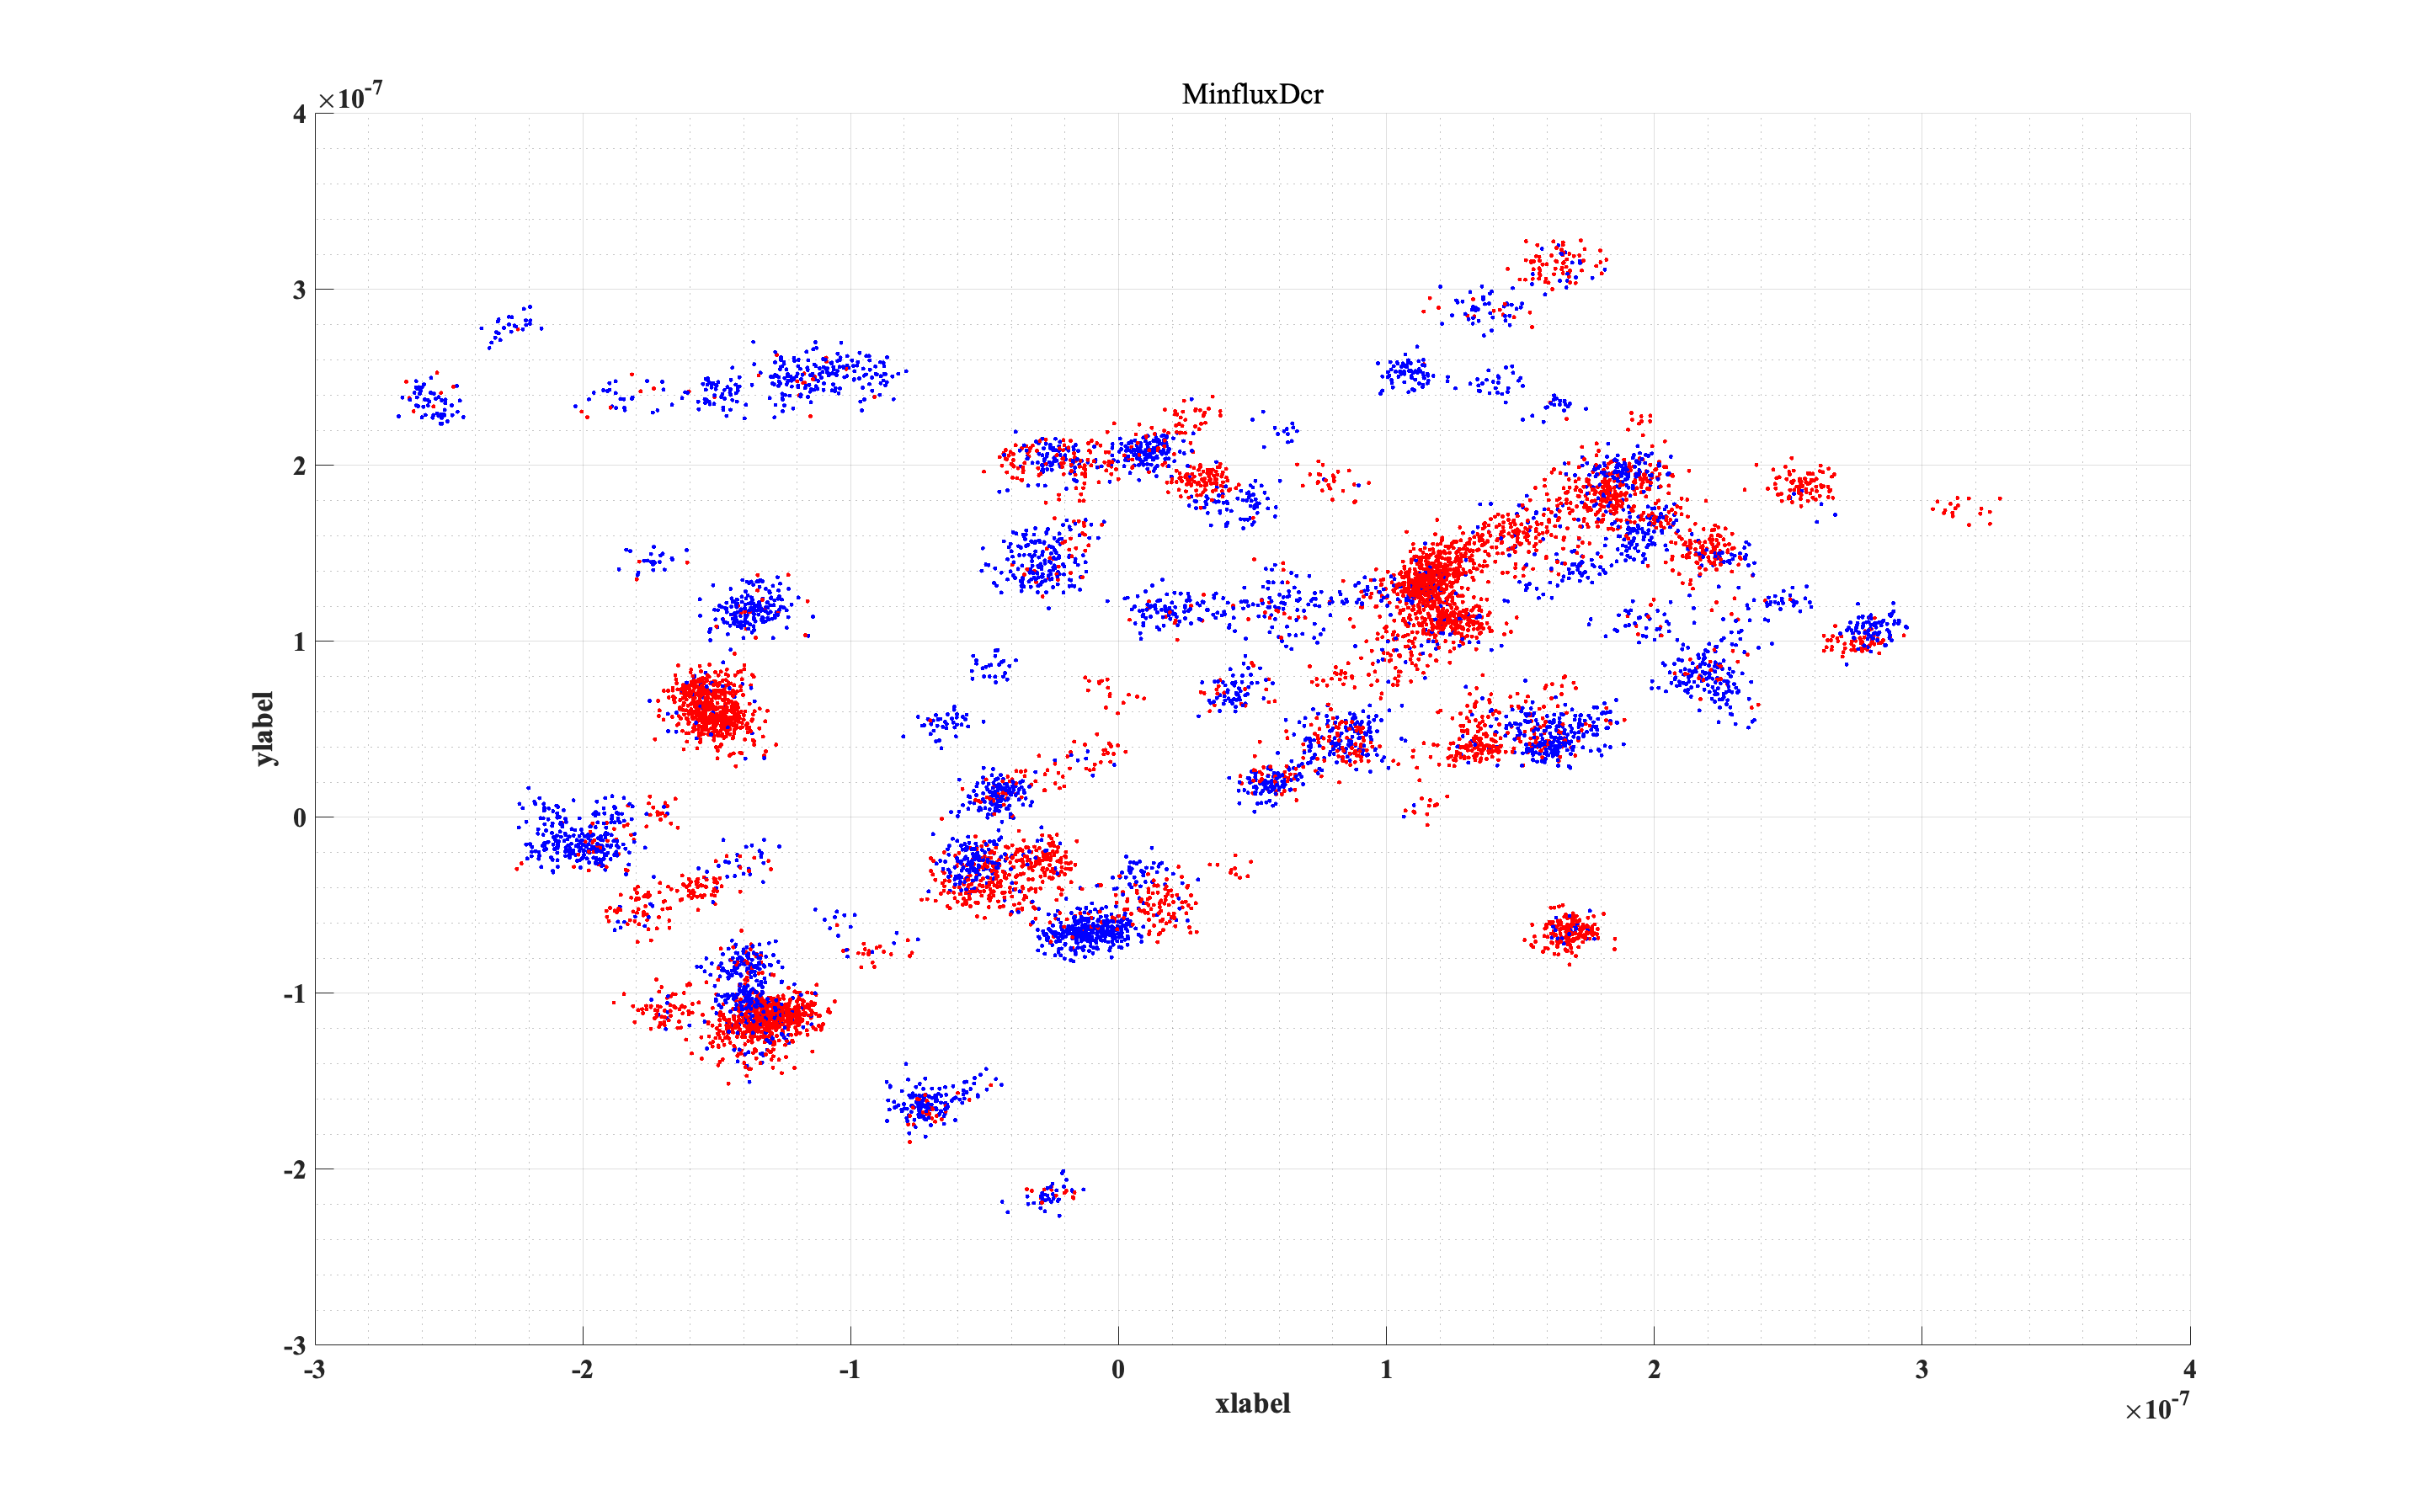

threshold = 0.58721;
loc = loc_nonoise;
frame = 68;

if ~isempty(loc) && ~isempty(loc)
    l1 = floor(256*threshold);
    l2 = floor(256*(1-threshold));
    bar1 = [linspace(0, 0, l1)', linspace(0, 0, l1)', linspace(1, 1, l1)'];
    bar2 = [linspace(1, 1, l2)', linspace(0, 0, l2)', linspace(0, 0, l2)'];
    colormap(cat(1, bar1, bar2))
else
    colormap([1, 0, 0])
end

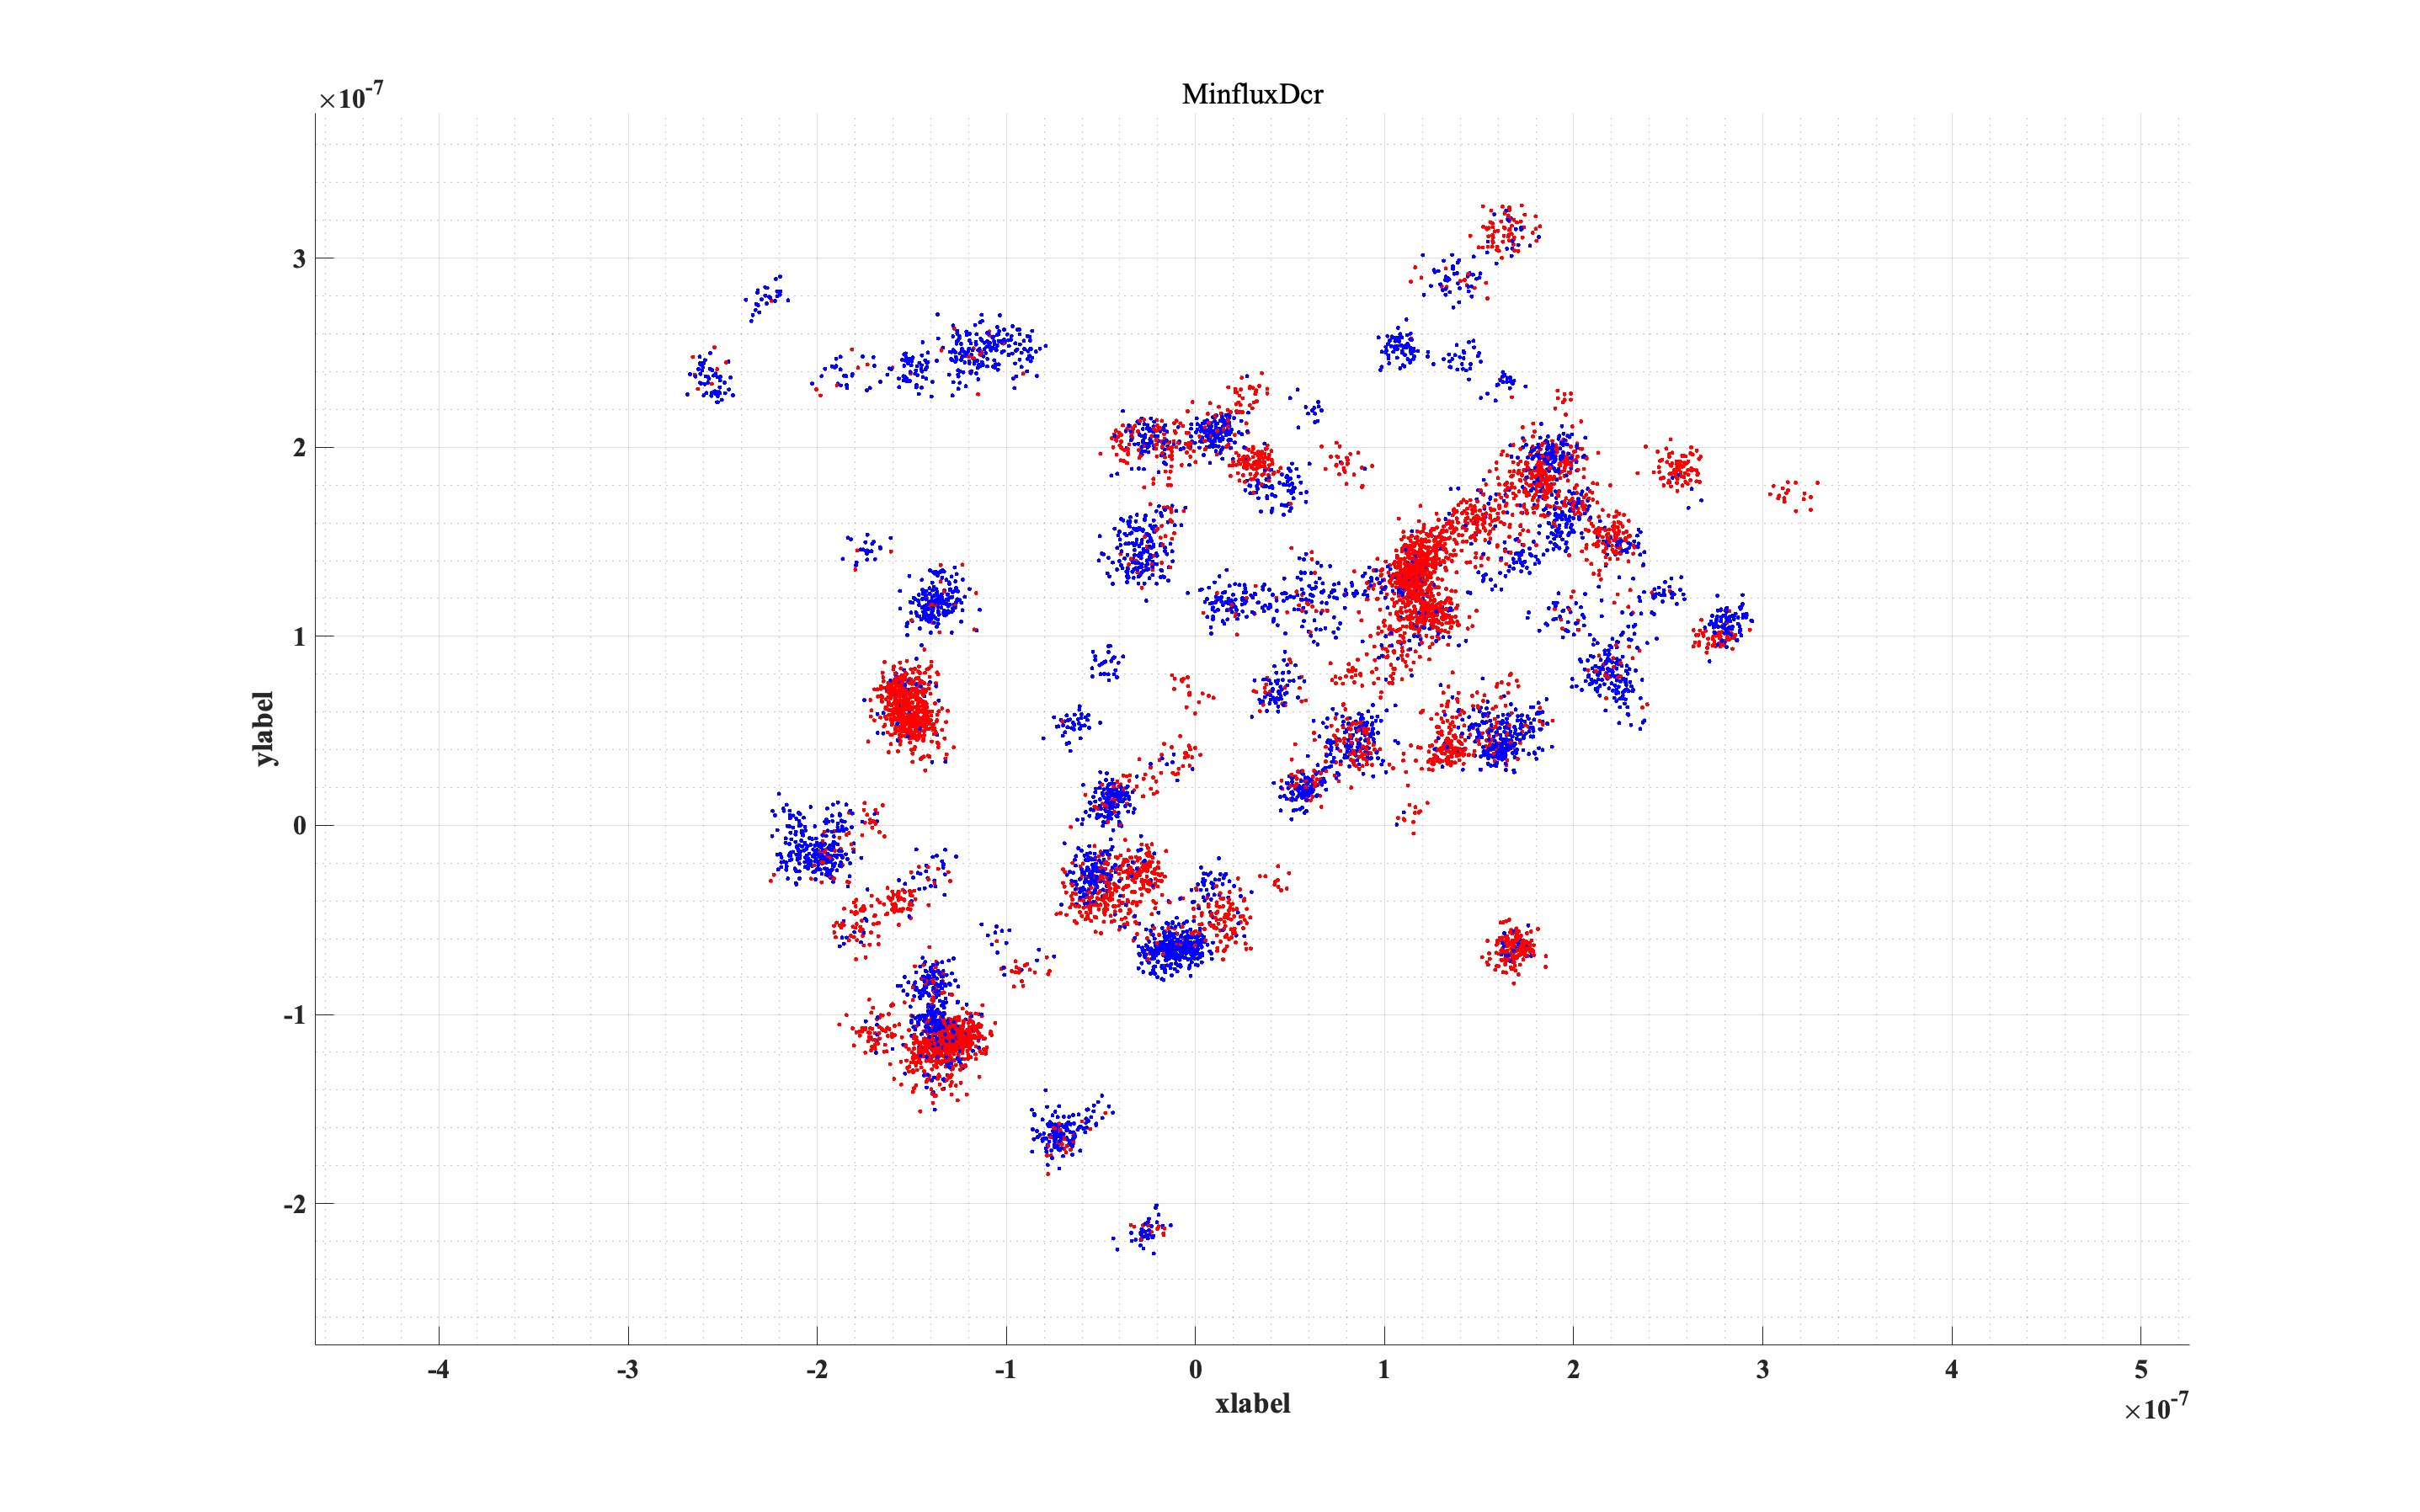


loc_idxr = find(dcr >= threshold);
loc_idxb = find(dcr < threshold);

plot3(loc(loc_idxr, 1), loc(loc_idxr, 2), loc(loc_idxr, 3), 'r.');
hold on;
plot3(loc(loc_idxb, 1), loc(loc_idxb, 2), loc(loc_idxb, 3), 'b.');
hold off;

fig = gcf;
ax = gca;

view([0, 0, 1])
axis equal
xlabel('xlabel')
ylabel('ylabel')
zlabel('zlabel')
title('MinfluxDcr');
set(ax, 'xgrid', 'on');
set(ax, 'ygrid', 'on');
set(ax, 'zgrid', 'on');
set(ax, 'xminorgrid', 'on');
set(ax, 'yminorgrid', 'on');
set(ax, 'zminorgrid', 'on');
set(ax, 'FontSize', 16, 'FontWeight', 'bold', 'FontName', 'Times New Roman');

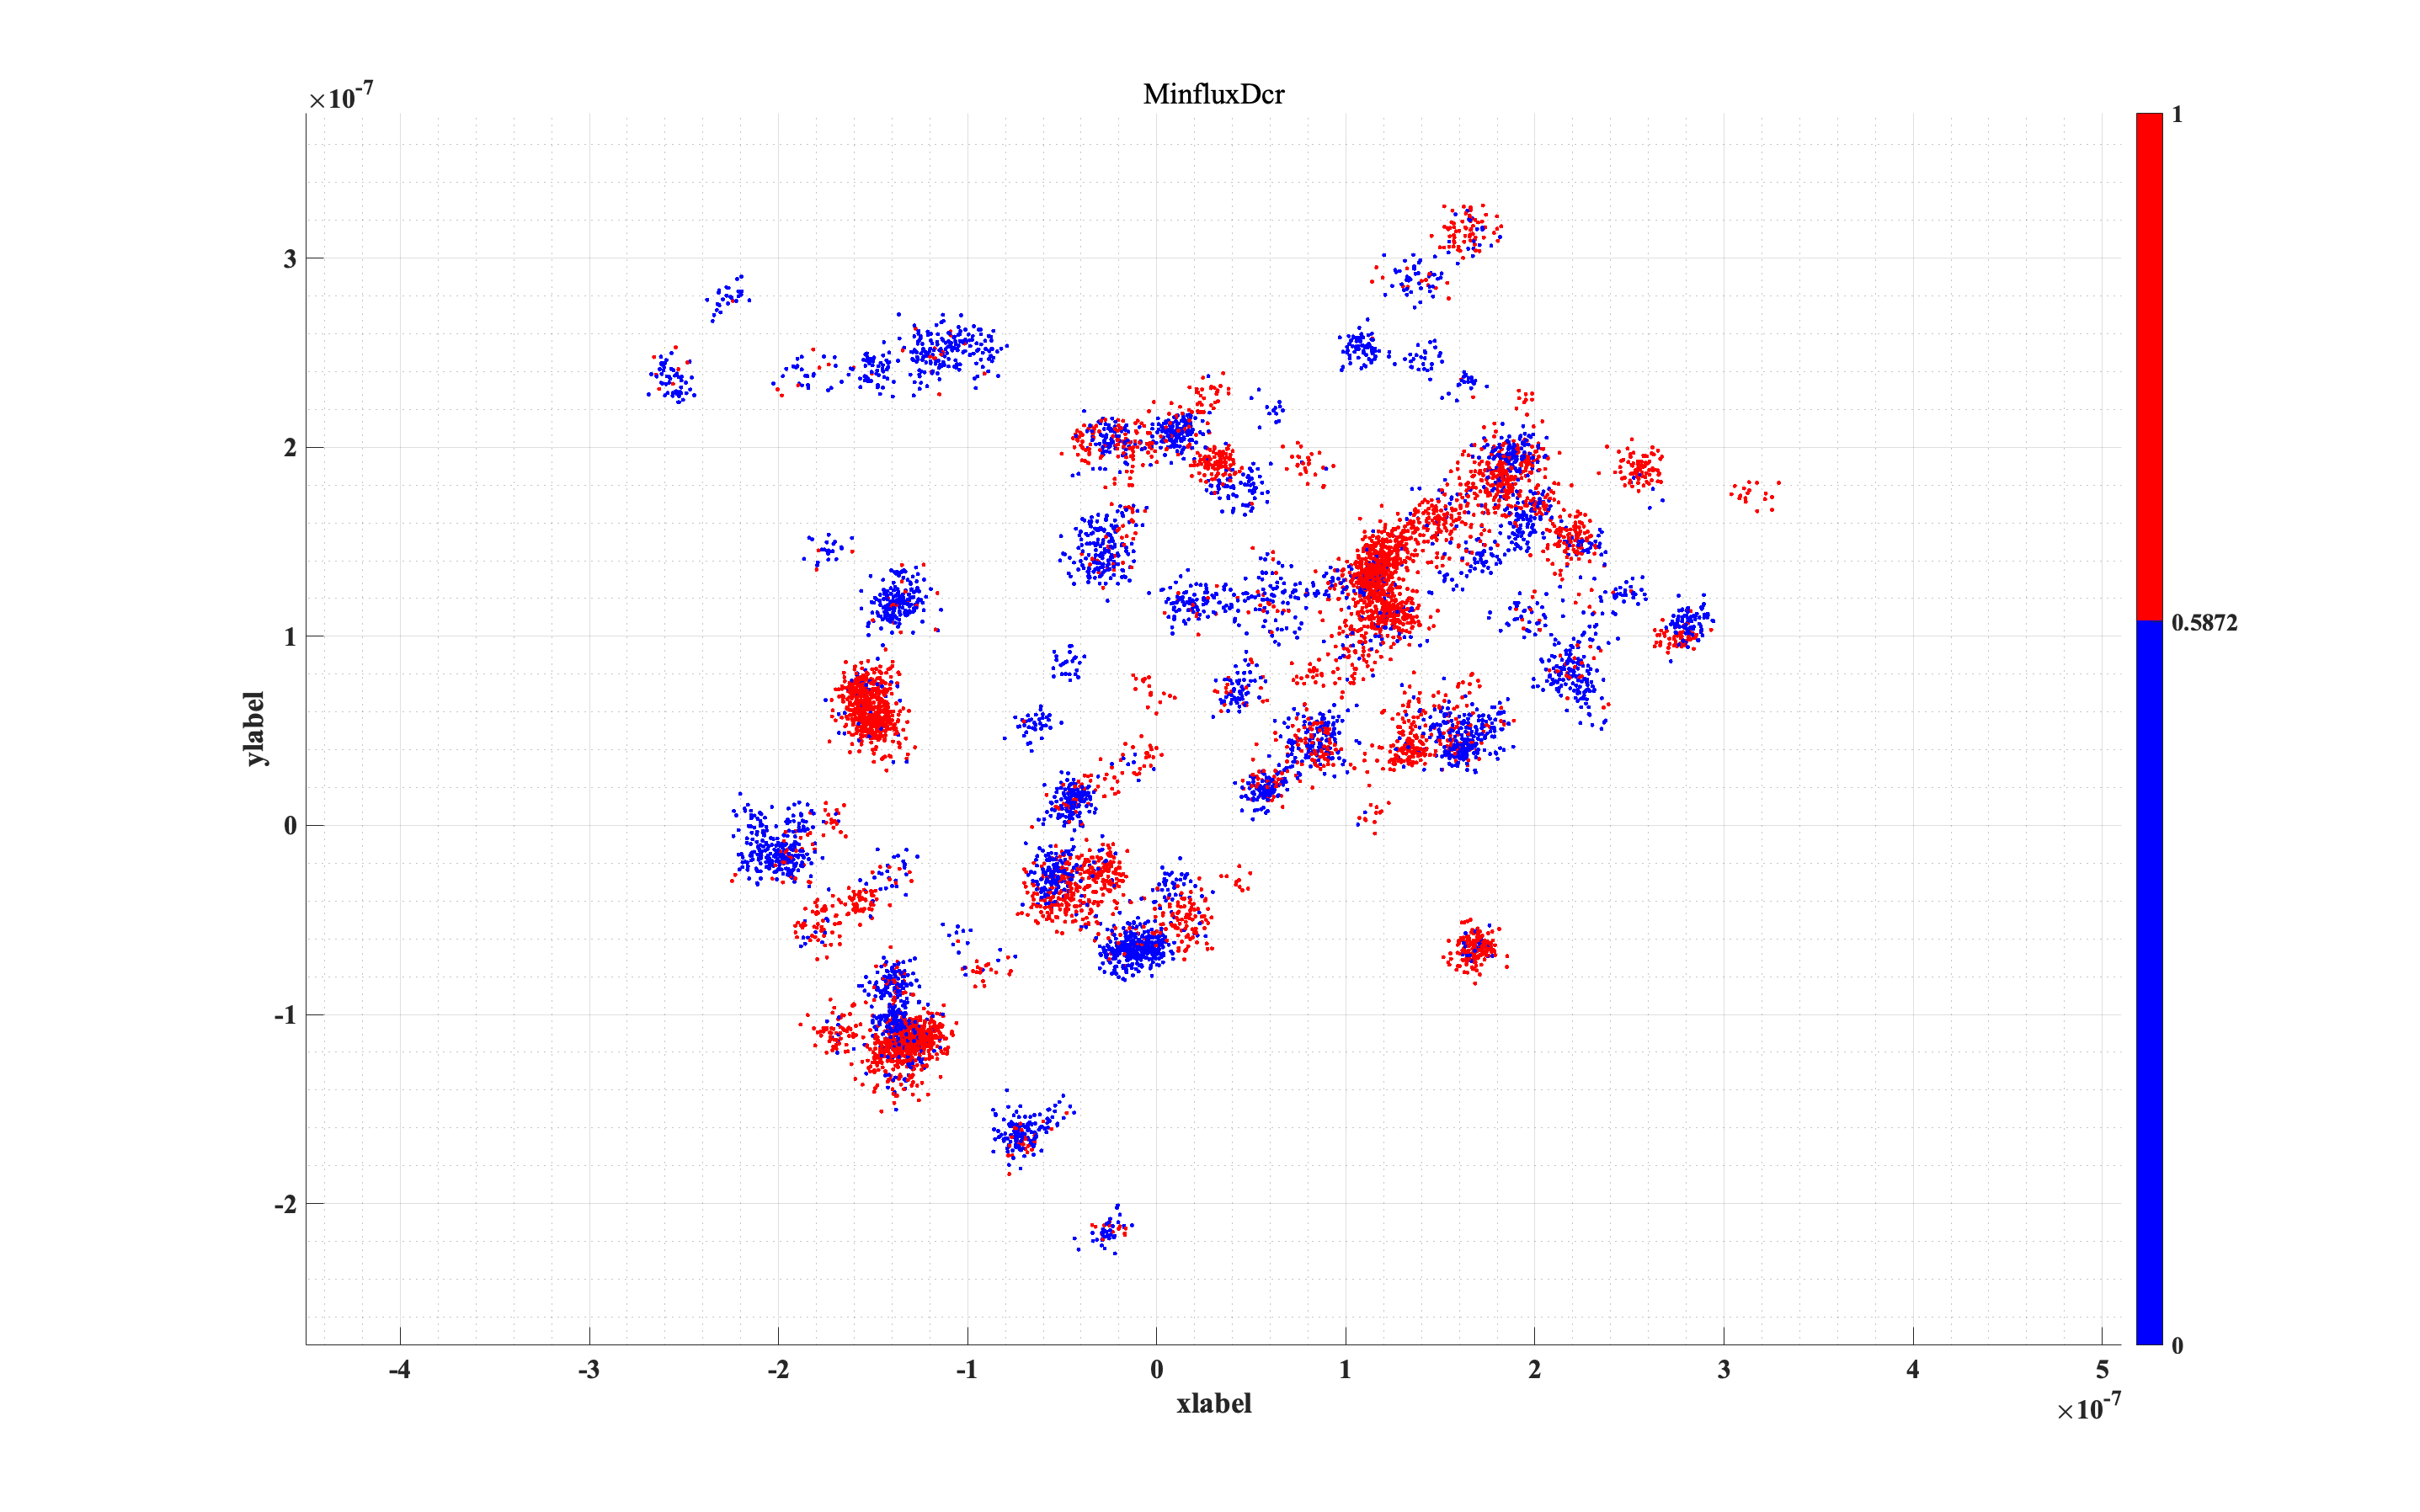

alp = 360/frame;
for i = 1 : frame
    
    axis equal
    colorbar('Ticks',[0, threshold, 1]);
    scrsz = get(0, 'ScreenSize');
    set(fig, 'Position', scrsz);
       
    rotate(ax.Children, [1, 0, 0], alp)
    drawnow
    f = getframe(fig);
    im{i} = frame2im(f);
    
end

name = 'RotateMinflux1.gif';
for k = 1 : frame
    [cdata, cmap] = rgb2ind(im{k}, 256);
    if k == 1
        imwrite(cdata, cmap, name, 'gif', 'LoopCount', Inf, 'DelayTime', 12/frame);
    else
        imwrite(cdata, cmap, name, 'gif', 'WriteMode', 'append', 'DelayTime', 12/frame);
    end
end